**P1**

function  [p_n, ci] = run_sim(n, N)
seed = 27;
rng(seed, "v5uniform")
DAYS_IN_YEAR = 365;

failures = zeros(N,1); % fails before a success

for N_idx = 1 : N
    bd = randi([1, DAYS_IN_YEAR], n); % gen rand birthdays
    birthday_count = zeros(365, 1);
    
    for n_idx = 1 : n
        birthday_count(bd(n_idx)) = birthday_count(bd(n_idx)) + 1;
        if (birthday_count(bd(n_idx)) == 2)
            break;
        end
        failures(N_idx) = failures(N_idx) + 1;
    end
    % birthday_count
end

success_occcured = failures ~= n; % found atleast 1 coinciding bd
p_n = mean(success_occcured);
V = var(success_occcured);
ci = [p_n - 1.96* sqrt(V/n), p_n + 1.96* sqrt(V/n)];
end

**a.) p_10**

N = 10000;
n = 10;

[p_n, ci] = run_sim(n, N)

p_n = 0.1198

ci =    -0.0815    0.3211


**b.) p_20**

n = 20;

[p_n, ci] = run_sim(n, N)

p_n = 0.4170

ci =     0.2009    0.6331


**c.) p_30**

n = 30;

[p_n, ci] = run_sim(n, N)

p_n = 0.7076

ci =     0.5448    0.8704


**d.)**


n_max = 50;

p = zeros(n_max,1);
ns = [1 : n_max]';
for n = [1 : n_max]
    p(n) = run_sim(n, N);
end
intersection = [find(abs(p - 0.5) <= (0.01)), 0.5] % get closest to 0.5

intersection =    23.0000    0.5000


[p_n, ci] = run_sim(intersection(1), N)

p_n = 0.5061

ci =     0.3018    0.7104


**Plot**

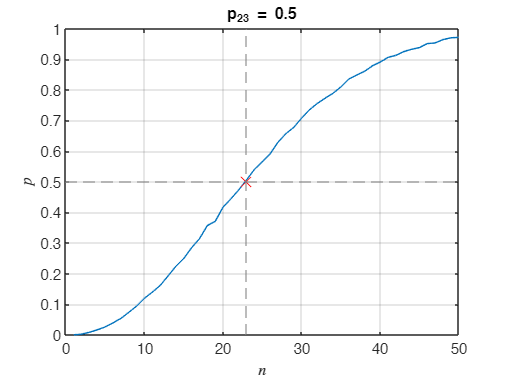

plot(ns, p)
hold on;
plot(intersection(1), intersection(2), 'red', Marker='x', MarkerSize=10)
yline(intersection(2), LineStyle="--", Color=[0.5, 0.5, 0.5,])
xline(intersection(1), LineStyle="--", Color=[0.5, 0.5, 0.5,])
title(sprintf('p_{%d} = 0.5', intersection(1)))
xlabel('$n$', 'Interpreter','latex')
ylabel('$p$', 'Interpreter','latex')
grid("on")
xlim([0,50])
ylim([0,1])
hold off;

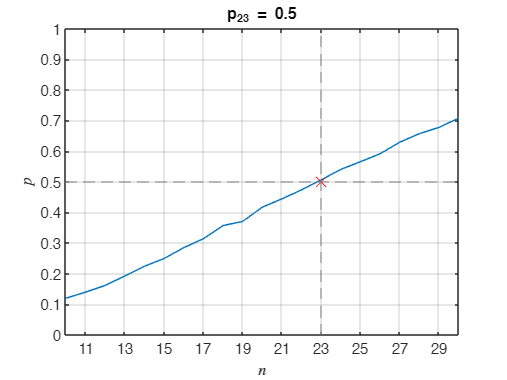


plot(ns, p)
hold on;
plot(intersection(1), intersection(2), 'red', Marker='x', MarkerSize=10)
yline(intersection(2), LineStyle="--", Color=[0.5, 0.5, 0.5,])
xline(intersection(1), LineStyle="--", Color=[0.5, 0.5, 0.5,])
xticks(1:2:n_max)
title(sprintf('p_{%d} = 0.5', intersection(1)))
xlabel('$n$', 'Interpreter','latex')
ylabel('$p$', 'Interpreter','latex')
grid("on")
xlim([10,30])
ylim([0,1])
hold off;